#### BME 4400 Vanderbilt University

#### Professor Mark D. Does

# Convolution Demo

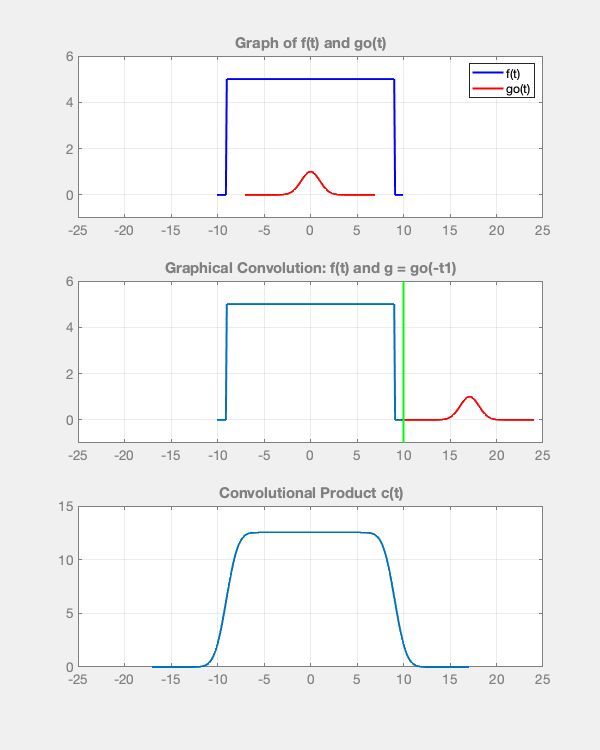

clear all
% close all
clc

aconv % function defined at the bottom of this file

% try changing definitions of f(t) and go(t) in 'aconv' to see convolution
% of different functions

## convolution -- practical implementation

Consider, for example, the convolution of a rect function with itself.

close all
clear all
clc

x = linspace(-5,5,201); % for med imaging, units are usually m (or cm or mm)
dx = diff(x(1:2)); % sampling period

L = 1; % width or rect pulse ... like rect(x/L) in text

Create a function that generates a rectangular signal in `x` with width `L`.

rct = @(x,L)(heaviside(-x+L/2)+heaviside(x+L/2)-1)

rct = function_handle with value:
    @(x,L)(heaviside(-x+L/2)+heaviside(x+L/2)-1)


figure(1)
plot(x,rct(x,L)), axis([-2.5 2.5 -0.5 2])
xlabel('x'), title('rect(x) from heaviside functions')
grid on

Use MATLAB's built in convolution function `conv`.

% convolution of a rectangular pulse with itself
help conv

 conv Convolution and polynomial multiplication.
    C = conv(A, B) convolves vectors A and B.  The resulting vector is
    length MAX([LENGTH(A)+LENGTH(B)-1,LENGTH(A),LENGTH(B)]). If A and B are
    vectors of polynomial coefficients, convolving them is equivalent to
    multiplying the two polynomials.
 
    C = conv(A, B, SHAPE) returns a subsection of the convolution with size
    specified by SHAPE:
      'full'  - (default) returns the full convolution,
      'same'  - returns the central part of the convolution
                that is the same size as A.
      'valid' - returns only those parts of the convolution 
                that are computed without the zero-padded edges. 
                LENGTH(C)is MAX(LENGTH(A)-MAX(0,LENGTH(B)-1),0).
 
    Class support for inputs A,B: 
       float: double, single
 
    See also deconv, conv2

Note the different options to crop the length of the output. The option '`same`' is a good choice for many cases, resuling in an output signal equal in length to the input signal, `A`.

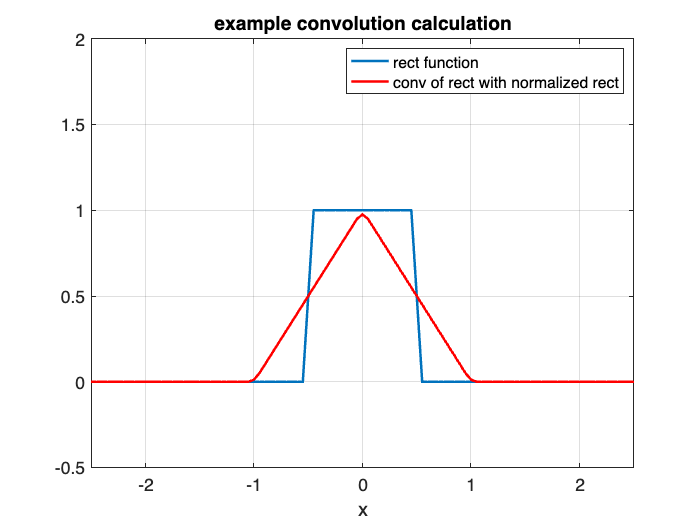

y = rct(x,L);
g = conv(y,y,'same')*dx;

hold on
plot(x,g,'r'), axis([-2.5 2.5 -0.5 2])
title('example convolution calculation')
legend('rect function','conv of rect with normalized rect')

Regarding output signal amplitudes, note the following. 

 First, the `conv` function does not include the $dx$ weighting in the integral calculation. In general, use `conv(f,g)*dx` to account for the sample period.

Second, the area of the output function will equal the area of the first input times the area of the second input. In the case where the second input is a system impulse response or filter, if you make its integrated area = 1, then the convolution operation won't scale the signal up or down, in terms of integrated area.

## 2D convolution -- practical implementation

clear all
close all
clc

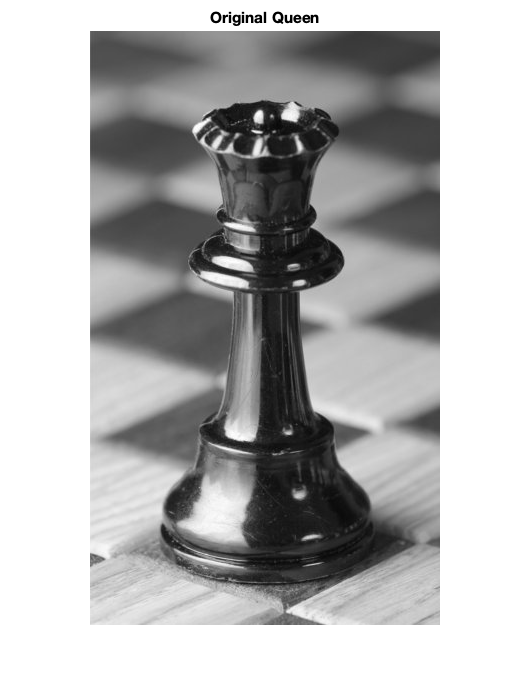

IMG = rgb2gray(imread('Chess_piece.jpg'));
imshow(IMG)
title('Original Queen')

Let's create a 2D impulse response that will blur the image.

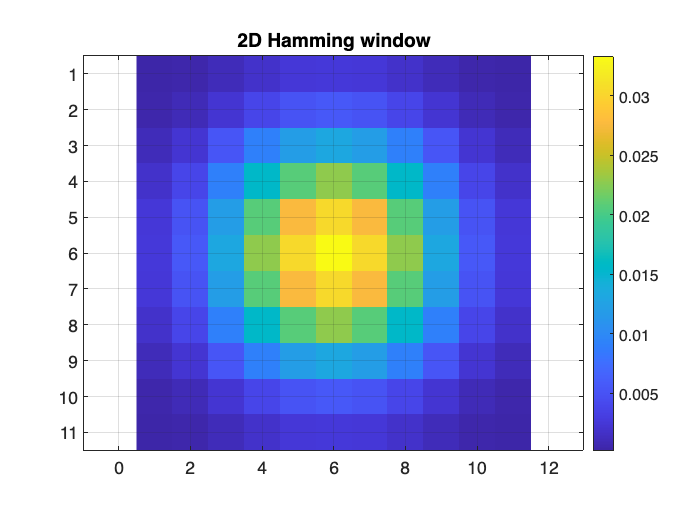

Nblur = 11; % Try differently sized impulse responses
h = hamming(Nblur)*hamming(Nblur)';
h = h./sum(h(:)); % normalize the area
figure(2)
imagesc(h), axis equal, colorbar
title('2D Hamming window')

The index spacing is arbitrary here, so I'll just assume it equals 1 in each direction, hence there's no need to account for the $dx$ and $dy$ terms.

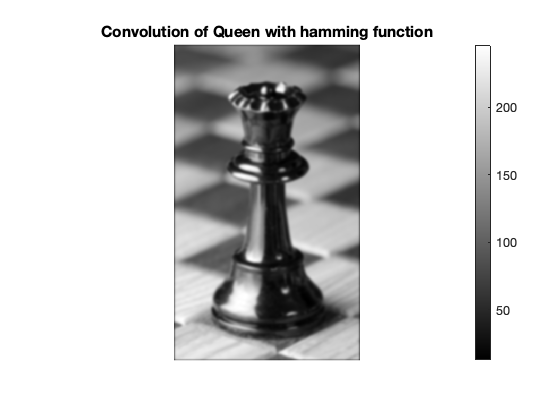

IMG_output = conv2(double(IMG),h,'same');

figure(3)
imagesc(IMG_output), axis('equal'), colormap(gray), colorbar, axis('off')
title('Convolution of Queen with hamming function')

The blurring effect is obvious. The greater Nblur, the greater the blurring effect.

## Extracting data from images

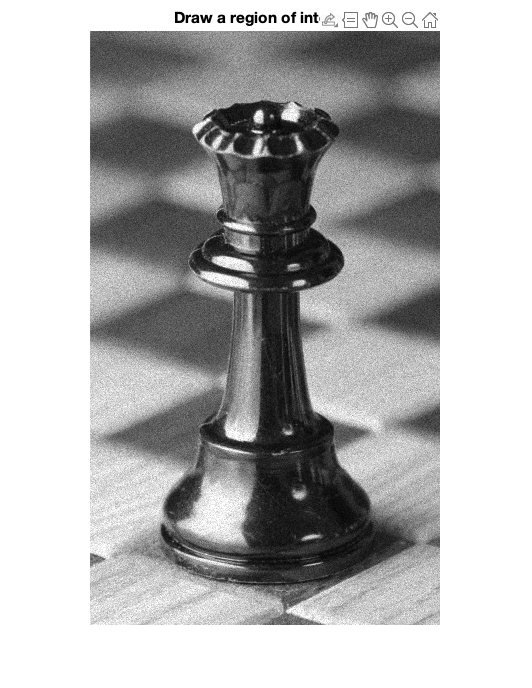

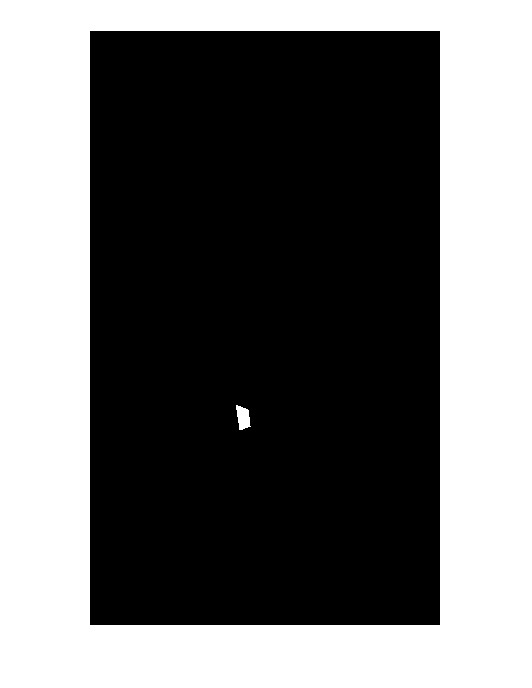

clear all
close all
clc

IMG_RGB = imread('Chess_piece.jpg');

% first note that an RGB image can be converted to an intensity image using
% the rgb2gray function

IMG = rgb2gray(IMG_RGB);

% add noise
IMGn = imnoise(IMG,'poisson');

imshow(IMGn)

% from here, we can extract data from Regions-of-Interest (ROIs) using one
% of several tools in MATLAB

% roipoly requires you to draw a polygon region in the image, then returns
% a mask of that image (1s inside the polygon, 0s outside the polygon).
title('Draw a region of interest')

mask = roipoly;
figure
imshow(mask)


% extract the mean and SD of the image intensity from within the mask
roi_mean = mean(IMGn(mask))

roi_mean =    190.7461e+000


% matlab treats 'mask' as a logical index and returns a column vector from
% IMGn(mask)


% likewise for the SD
roi_sd = std(single(IMGn(mask)))

roi_sd = single
    22.0886e+000



% note that function 'mean' accepts uint8 data as input but 'std' does not,
% so you must first convert it to single or double. 

% In general, you can avoid a lot of headaches related to data type
% (at the expense of filling up computer memory) 
% by using double precision for all image data


#### Displaying text and/or data on your figure

To add arbitrary text and/or data to a figure, use the `text`, `gtext`, or `annotate` commands, along with `num2str`, `int2str`, or (better), `sprintf`. For example, label the ROI intensity mean and standard deviation.

figure(1), clf
imshow(IMGn)
strg = sprintf('ROI mean = %0.1f ± %0.2f',roi_mean,roi_sd)

strg = 'ROI mean = 190.7 ± 22.09'

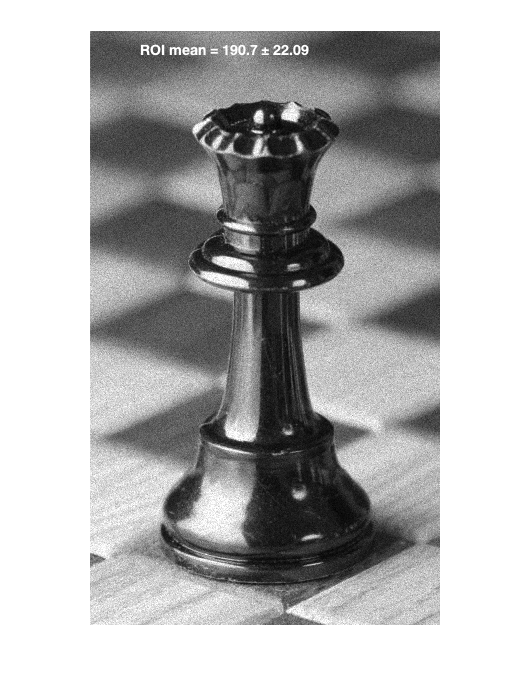

t1 = text(50,20,strg,'FontWeight','Bold','Color','w');
t1.FontSize = 14;

function aconv()
% %%%%%%%%%%%%%%%%%%%%% Function: acnv.m %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
%  Title: Animation of Graphical Convolution
%
%  Description:
%   1. This is a simple MatLab demo to animate the process of convolution.
%      It is meant to help student to visualize how convolution works.
%
%   2. When this script is run, two function f(t) and go(t) are convolved
%      and the output figure will show animated graphical convolution.
%
%   3. The functions "f" and "go" and their range of interval can be changed
%      by editing this script at line numbers around "48 to 64"
%
%   4. Note:  For a better scaled plots of the functions f(t) and go(t1),
%             it is recommended to set the functions such that their
%             maximum value remains comparable. e.g one can use appropriate
%             scaling. Other functions are also given 'commented out'
%
%             Interger values are recommended for the intervals
%
%   5. The animation can be made faster or slower by changing the value of
%      the pause function in the animation loop. (around line number 134)
%
%  Author:
%      Laine Berhane Kahsay
%      Uni-Ulm, Germany
%
%   email: kahsay_2004@yahoo.com
%
%     ver: 1.0, written in Matlab 6.5/7.0
%
%  To see this help - type on the Matlab Prompt: > help acnv
%
%  Modified multiple times by Mark Does for his very appreciative BME 4400 students
%   MDD EraseMode removed to maintain compatibility with new MATLAB release
%
% MDD added for live script, along with 'Visible','On' for the figure
s = settings;
s.matlab.editor.AllowFigureAnimation.TemporaryValue = 1;
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%

% help aconv;

% color of axis constant
axis_color= [0.5 0.5 0.5];

% sampling interval constant
s_int = 0.1;

% interval for function 'f(t)'
t = [ -10:s_int:10 ];

% definition of function 'f(t)'
% MDD try different functions here
%    f = 0.1*(t.^2);
f = [zeros(1,10),5*ones(1, length(t)-20),zeros(1,10)];
%  f = t;

% interval for function 'go(t1)'
t1 = [-7:s_int:7];

% definition of function 'go(t1)'
% MDD try different functions here
% go = -0.1*(t1.^2);
go = exp(-t1.^2/2);
% go = sinc(t1)
% go = 5*cos(2*pi*t1);
% go = 5*ones(1, length(t1));
% go = zeros(1, length(t1));go(1)=5;


% convolve: note the multiplation by the sampling interval
c = s_int * conv(f, go);

% Animation %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% flip 'go(t1)' for the graphical convolutions g = go(-t1)
g = fliplr(go);
tf = fliplr(-t1);

% slide range of 'g' to discard non-ovelapping areas with 'f' in the convolution
tf = tf + ( min(t)-max(tf) );

% get the range of function 'c' which is the convolution of 'f(t)' and 'go(t1)'
tc = [ tf t(2:end)];
tc = tc+max(t1);

% start graphical output with three subplots
a_fig = figure;
set(a_fig, 'Name', 'Animated Convolution', 'unit', 'pixel', ...
    'Position', [300, 150, 600, 750],'Visible','On');

% plot f(t) and go(t1)
ax_1 = subplot(3,1,1);
op = plot(t,f, 'b',  t1, go, 'r','LineWidth',2');
hold on; grid on;
set(ax_1, 'XColor', axis_color, 'YColor', axis_color, 'Color', 'w');
xlim( [ ( min(t)-abs(max(tf)-min(tf)) - 1 ) ...
  ( max(t)+abs(max(tf)-min(tf)) + 1 ) ] );
ylim([min([f,g])-1,max([f,g])+1]);
title('Graph of f(t) and go(t)', 'Color', axis_color );
legend({'f(t)' 'go(t)'});

% initialize animation the plot of 'g' is slided over the plot of 'f'

% plot f in the subplot number 2
ax_2 = subplot(3,1,2);
p = plot(t, f,'LineWidth',2');
hold on; grid on;
title('Graphical Convolution: f(t) and g = go(-t1)', 'Color', axis_color );

% plot g in the subplot number 2
q = plot(tf, g, 'r','LineWidth',2');
xlim( [ ( min(t)-abs(max(tf)-min(tf))-1 ) ...
  ( max(t)+abs(max(tf)-min(tf))+1 ) ] );
ylim([min([f,g])-1,max([f,g])+1]);

u_ym = get(ax_2, 'ylim');

% plot two vertical lines to show the range of ovelapped area
s_l = line( [min(t) min(t)], [u_ym(1) u_ym(2)], 'color', 'g'  );
e_l = line( [min(t) min(t)], [u_ym(1) u_ym(2)], 'color', 'g'  );
hold on; grid on;
set(ax_2, 'XColor', axis_color, 'YColor', axis_color, 'Color', 'w');

% put a yellow shade on ovelapped region
sg = rectangle('Position', [min(t) u_ym(1) 0.0001 u_ym(2)-u_ym(1)], ...
    'EdgeColor', 'w', 'FaceColor', 'y'); %, ...
%     'EraseMode', 'xor');


% initialize the plot the convolution result 'c'
ax_3 = subplot(3,1,3);
r = plot(tc, c,'LineWidth',2');
grid on; hold on;
set(ax_3, 'XColor', axis_color, 'YColor', axis_color);
% xlim( [ min(tc)-1 max(tc)+1 ] );
xlim( [ ( min(t)-abs(max(tf)-min(tf)) - 1 )...
  ( max(t)+abs(max(tf)-min(tf)) + 1 ) ] );
title('Convolutional Product c(t)', 'Color', axis_color );
pause
% animation block
for i=1:length(tc)

   % control speed of animation minimum is 0, the lower the faster
    pause(0.01);
    drawnow;
    
    % update the position of sliding function 'g', its handle is 'q'
    tf=tf+s_int;
%     set(q,'EraseMode','xor');
    set(q,'XData',tf,'YData',g);
    
    % show overlapping regions
    
    % show a vetical line for a left boundary of overlapping region
    sx = min( max( tf(1), min(t) ), max(t) );
    sx_a = [sx sx];
%     set(s_l,'EraseMode','xor');
    set(s_l, 'XData', sx_a);
    
    % show a second vetical line for the right boundary of overlapping region
    ex = min( tf(end), max(t) );
    ex_a = [ex ex];
%     set(e_l,'EraseMode','xor');
    set(e_l, 'XData', ex_a);
    
    % update shading on ovelapped region
    rpos = [sx u_ym(1) max(0.0001, ex-sx) u_ym(2)-u_ym(1)];
    set(sg, 'Position', rpos);
    uistack(sg, 'bottom'); % <-- THIS LINE HERE

    
    % update the plot of convolutional product 'c', its handle is r
%     set(r,'EraseMode','xor');
    set(r,'XData',tc(1:i),'YData',c(1:i) );
    
end
%
% end of acnv %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
end